# Jacobi orthogonal polynomials

Weight function $\omega \left(x\right):={\left(1-x\right)}^{\alpha \;} {\left(1+x\right)}^{\beta \;} \;$defined on the interval $\left\lbrack -1,1\right\rbrack$.

a = 6; b = 6; 
syms x real
w = (1-x)^a *(1+x)^b;   % weight function (symmetric if a=b)

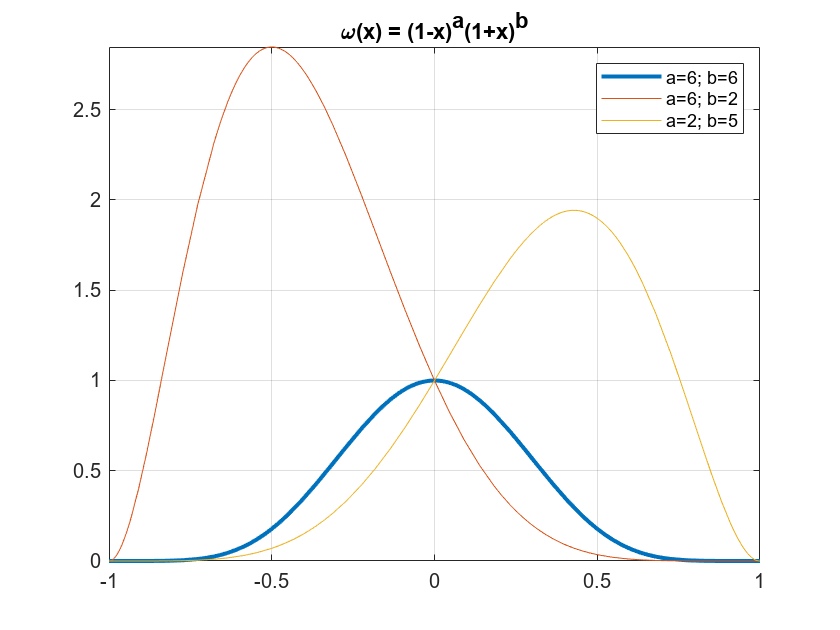

fplot (w, [-1 1], LineWidth=2)
hold on
fplot((1-x)^6*(1+x)^2, [-1 1])
fplot((1-x)^2*(1+x)^5, [-1 1])
grid on
title("\omega(x) = (1-x)^a(1+x)^b")
legend(["a=6; b=6", "a=6; b=2", "a=2; b=5"])

Jacobi polynomials are defined on the interval $\left\lbrack -1,1\right\rbrack$

N = 5; 
J = jacobiP(0:N, a, b, x)'    % N+1 Jacobi polynomials of degree 0,1,2 ,... ,N

$$J = \left(\begin{array}{c} 1\\ 7\,x\\ 30\,x^{2}-2\\ 102\,x^{3}-18\,x\\ \frac{4845\,x^{4}}{16}-\frac{765\,x^{2}}{8}+\frac{45}{16}\\ \frac{13167\,x^{5}}{16}-\frac{3135\,x^{3}}{8}+\frac{495\,x}{16} \end{array}\right)$$

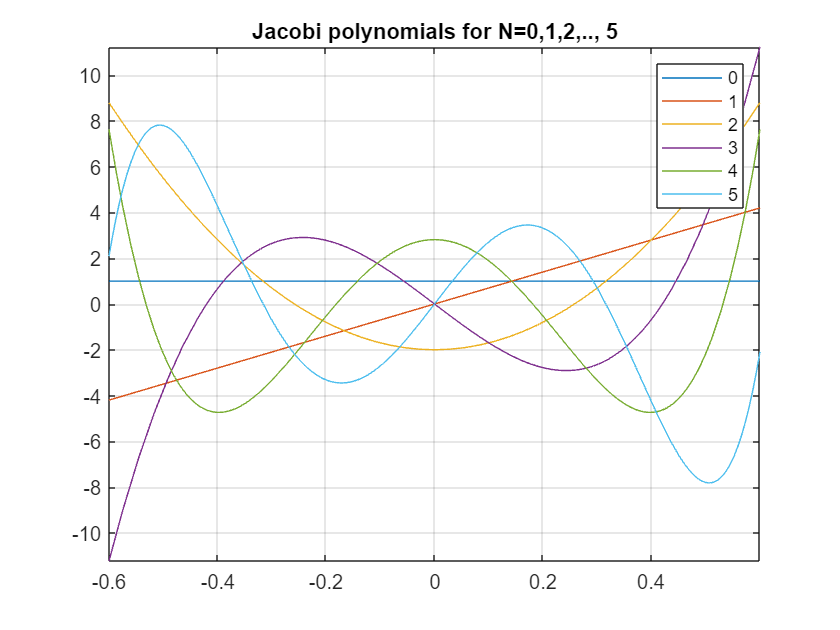


figure 
fplot (J, [-0.6,0.6]) 
title("Jacobi polynomials for N=0,1,2,.., 5")
legend (string(0:N))
grid on